Microstrip line impedance calc

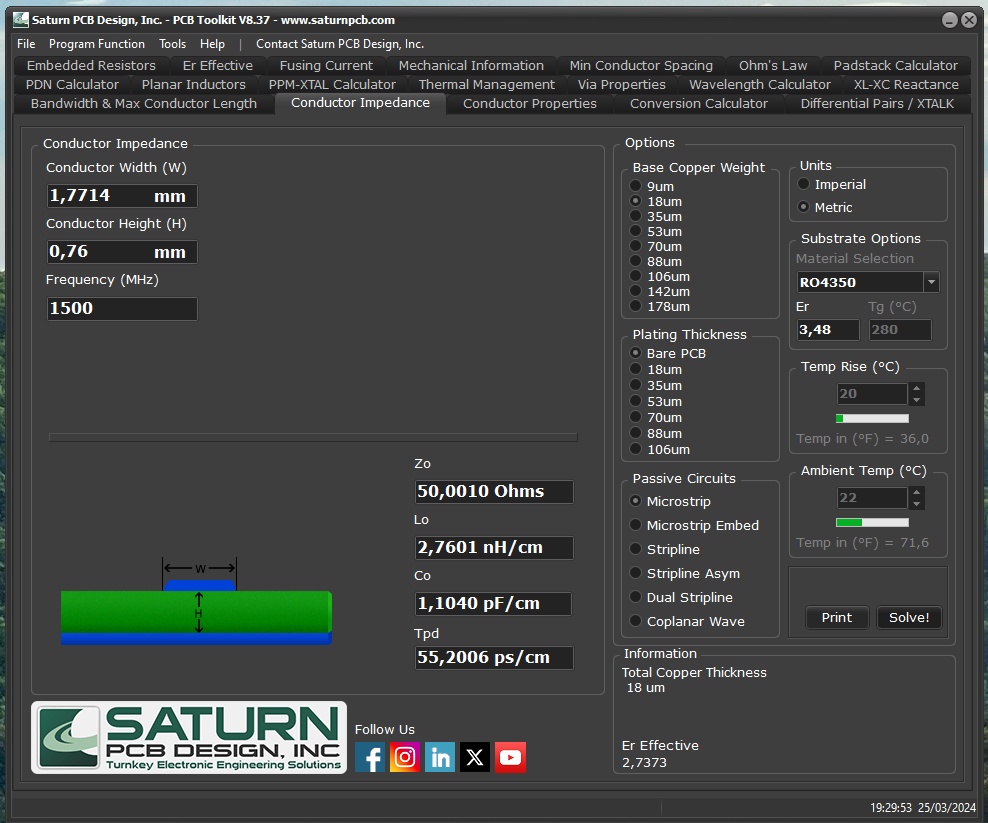

microstriptxline = txlineMicrostrip('Width',1.7714e-3,'Height',0.51e-3,'DielectricThickness',0.51e-3,'LineLength',10e-3,'Thickness',18e-06,'EpsilonR',3.48,'SigmaCond',1.68e8);
[z0,eff_ep] = getZ0(microstriptxline)

z0 = 37.3554

eff_ep = 2.8173

microstriptxline = txlineMicrostrip('Width',1.1e-3,'Height',0.51e-3,'DielectricThickness',0.51e-3,'LineLength',10e-3,'Thickness',18e-06,'EpsilonR',3.48,'SigmaCond',1.68e8);
[z0,eff_ep] = getZ0(microstriptxline)

z0 = 50.9847

eff_ep = 2.7110

Filter generation

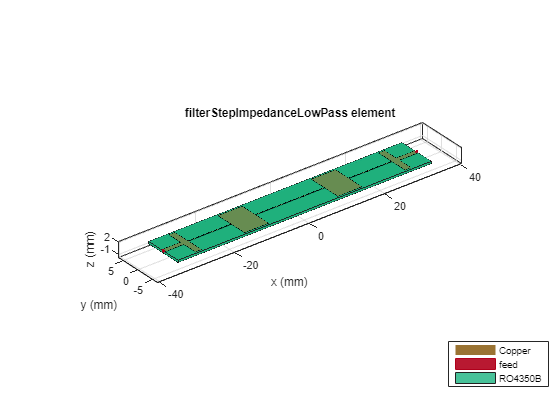

clc
clear all
close all

met = metal('copper');
met.Thickness = 18e-06; % 1/2 oz copper (18um)
sub = dielectric("RO4350B");
sub.Thickness = 0.51e-3;

steppedfilter = filterStepImpedanceLowPass;
steppedfilter.FilterOrder = 5;
steppedfilter.Height = sub.Thickness;
steppedfilter.PortLineLength = 5e-3;
steppedfilter.PortLineWidth = 1.7714e-3; % 50 ohm on this substrate
steppedfilter.LowZLineWidth = 25e-3;
steppedfilter.HighZLineWidth = 0.3e-3;
steppedfilter.GroundPlaneWidth = 30e-3;
steppedfilter.Substrate = sub;
steppedfilter.Conductor = met;

steppedfilter.FilterOrder = 7;
sifilt_15 = design(steppedfilter,1.5e9,Z0=50,LowZ=10,HighZ=110,FilterType="Butterworth"); % butterworth ker je frekvenca bližje zanimivem pasu - manj valovitosti
sifilt_15.PortLineLength = 5e-3;
steppedfilter.FilterOrder = 5;
sifilt_5 = design(steppedfilter,5e9,Z0=50,LowZ=10,HighZ=110,FilterType="Chebyshev"); % chebyshev za strmejše slabljenje
sifilt_5.PortLineLength = 5e-3;

filt = shapes(sifilt_15).Layer1 + translate(shapes(sifilt_5).Layer1, [45 0 0]*1e-3);
gnd = traceRectangular(Length = 110e-3, Width = 20e-3, Center = [10e-3, 0]); %* GND plane

figure(1)
show(sifilt_15)

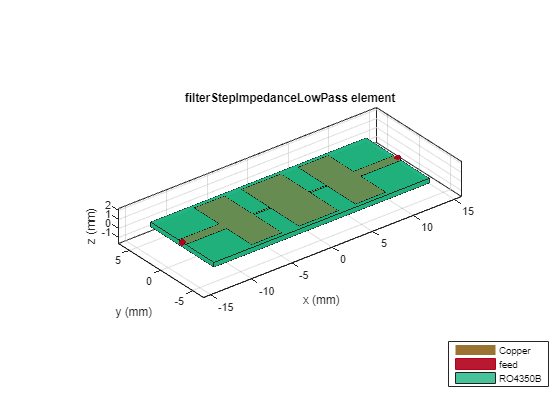

show(sifilt_5)

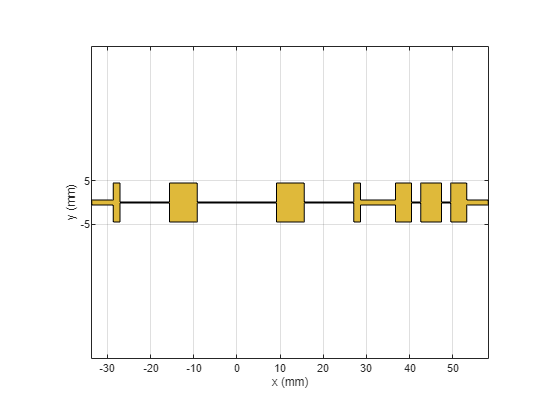

figure
show(filt)


pcb = pcbComponent(Conductor=met);
pcb.BoardShape = gnd;
pcb.BoardThickness = 0.76e-3;
pcb.Layers = {filt,sub,gnd};

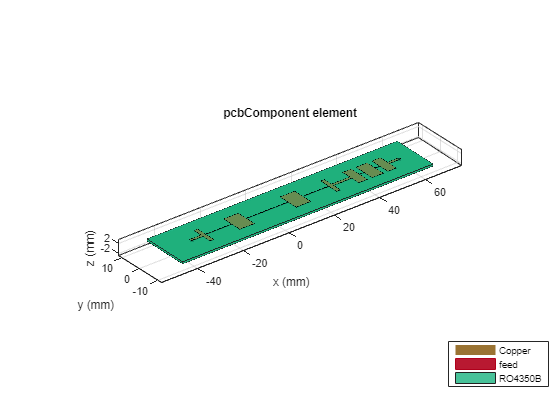

pcb.FeedDiameter = 1.7714e-3/2;
pcb.FeedLocations = [-33e-3 0 1 3;58e-3 0 1 3];
figure;
show(pcb);


spar = sparameters(pcb,linspace(1e6,17e9,40));
figure
rfplot(spar,[1 2], 1);

Unrecognized function or variable 'spar'.

legend(Location="southwest")
rfwrite(spar,'current_filter.s2p')